# Discrete wavelet transform (DWT) of monthly runoff 

Should work in MATLAB R2016a and above.

- Clear the workspace.

- Read monthly runoff.

- Set decomposition parameters and save path.

- Decompose the entire set.

- Decompose the training set.

- Decompose the training-development set.

- Decompose the appended set.

## 1 Clear workspace

clear
close all
clc

## 2 Read monthly runoff.

data_path='../time_series/';
station='Huaxian'; %'Huaxian', 'Xianyang' or 'Zhangjiashan'
switch station
    case 'Huaxian'
        save_path = '../Huaxian_dwt/data/';
        data = xlsread([data_path,'HuaxianRunoff1951-2018(1953-2018).xlsx'],1,'B26:B817');%full=792samples
    
    case 'Xianyang'
        save_path = '../Xianyang_dwt/data/';
        data = xlsread([data_path,'XianyangRunoff1951-2018(1953-2018).xlsx'],1,'B26:B817');%full=792samples
        
    case 'Zhangjiashan'
        save_path = '../Zhangjiashan_dwt/data/';
        data = xlsread([data_path,'ZhangJiaShanRunoff1953-2018(1953-2018).xlsx'],1,'B2:B793');%full=792samples
end

##  3 Set decomposition parameters of DWT.

% level=round(log10(l_td));%log10(552)=2.741939077729199
mother_wavelet = 'db10';% set mother wavelet
lev = 2; %same decomposition level as VMD
columns = {};
for i=1:lev+2
    if i==1
        columns{i}='ORIG';
    elseif i==lev+2
        columns{i}=['A',num2str(lev)];
    else
        columns{i}=['D',num2str(i-1)];
    end  
end
if exist([save_path,mother_wavelet,'-',num2str(lev),'/dwt-test/'],'dir')==0
   mkdir([save_path,mother_wavelet,'-',num2str(lev),'/dwt-test/']);
end

## 4 Decompose the entire set.

### 4.1 Decompose the entire set and extract approximation and detail coefficients

[C,L]=wavedec(data,lev,mother_wavelet);%Decompose the entire set
cA=appcoef(C,L,mother_wavelet,lev);%Extract the approximation coefficients from C
cD = detcoef(C,L,linspace(1,lev,lev));%Extract the detail coefficients from C

### 4.2 Reconstruct the level approximation and level details

A=wrcoef('a',C,L,mother_wavelet,lev); %the approximation
for i=1:lev
    eval(['D',num2str(i),'=','wrcoef(''d'',C,L,mother_wavelet,i)',';']); %the details
end

### 4.3 combine the details, appromaximation and original data into a single parameter and save decomposition results

signals=zeros(length(data),lev+2);
signals(:,lev+2)=A;
signals(:,1)=data;
for i=2:lev+1
    eval(['signals(:,i)','=','D',num2str(i-1),';']);
end
decompositions = array2table(signals, 'VariableNames', columns);
writetable(decompositions, [save_path,mother_wavelet,'-',num2str(lev),'/DWT_FULL.csv'])


## 5 Decompose the training set

### 5.1 Decompose the training set and extract approximation and detail coefficients

train_len = 552

train_len = 552

train=data(1:train_len);%train
[C,L]=wavedec(train,lev,mother_wavelet);
cA=appcoef(C,L,mother_wavelet,lev);
cD = detcoef(C,L,linspace(1,lev,lev));

### 5.2 Reconstruct the level approximation and level details

A=wrcoef('a',C,L,mother_wavelet,lev); %the approximation
for i=1:lev
    eval(['D',num2str(i),'=','wrcoef(''d'',C,L,mother_wavelet,i)',';']); %the details
end

### 5.3 combine the details, appromaximation and original data into a single parameter and save the decomposition results

train_signals=zeros(length(train),lev+2);
train_signals(:,lev+2)=A;
train_signals(:,1)=train;
for i=2:lev+1
    eval(['train_signals(:,i)','=','D',num2str(i-1),';']);
end
% save the decomposition results and the original data
train_decompositions = array2table(train_signals, 'VariableNames', columns);
writetable(train_decompositions, [save_path,mother_wavelet,'-',num2str(lev),'/DWT_TRAIN.csv'])


### 5.4 Plot the decomposition results of training set

f1=figure

f1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


set(f1,'position',[1500 1500 900 900]);
%%% tight_subplot(rowas,columns,[v-space,h-space],[bottom,top],[left,right])
ha = tight_subplot(lev+2,1,[.05 .08],[.05 .04],[.05 .02])

ha =     0.0012
    1.0012
    2.0012
    3.0012


for i=1:size(train_signals,2)
    if i==1
        axes(ha(i));
        plot(train,'r');
        title('Original training set');
    elseif i==size(train_signals,2)
        axes(ha(i));
        plot(A,'b');
        title(['Approximation A',num2str(lev)]);
    else 
        axes(ha(i));
        plot(train_signals(:,i-1),'g');
        title(['Detail D',num2str(i-1)]);
    end
end

## 6 Decompose the training-development set

### 6.1 Decompose the training set and extract approximation and detail coefficients

train_dev_len = 672;
train_dev=data(1:train_dev_len);
[C,L]=wavedec(train_dev,lev,mother_wavelet);
cA=appcoef(C,L,mother_wavelet,lev);
cD = detcoef(C,L,linspace(1,lev,lev));

### 6.2 Reconstruct the level approximation and level details

A=wrcoef('a',C,L,mother_wavelet,lev); %the approximation
for i=1:lev
    eval(['D',num2str(i),'=','wrcoef(''d'',C,L,mother_wavelet,i)',';']); %the details
end

### 6.3 Combine the details, appromaximation and original data into a single parameter and save decomposition results

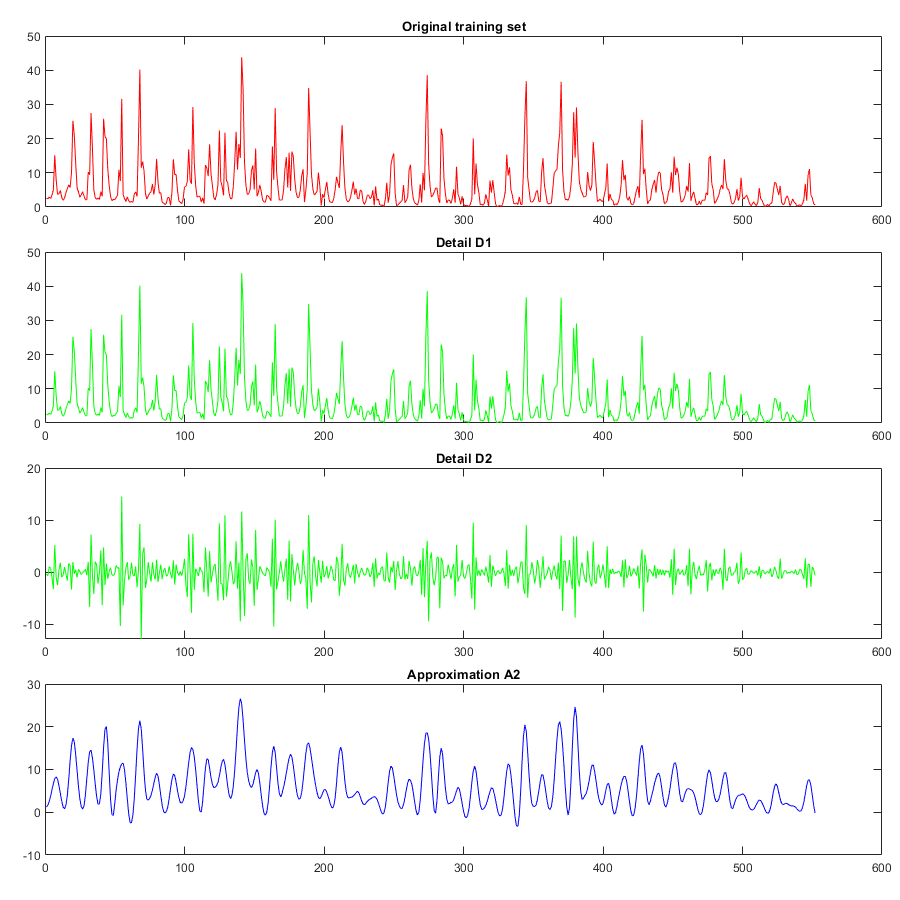

train_dev_signals=zeros(length(train_dev),lev+2);
train_dev_signals(:,lev+2)=A;
train_dev_signals(:,1)=train_dev;
for i=2:lev+1
    eval(['train_dev_signals(:,i)','=','D',num2str(i-1),';']);
end
train_dev_decompositions = array2table(train_dev_signals, 'VariableNames', columns);
writetable(train_dev_decompositions, [save_path,mother_wavelet,'-',num2str(lev),'/DWT_TRAINDEV.csv'])
save(['../results_analysis/results/',station,'-dwt.mat']);

## 7 Decompose the appended set

for i=1:240
    appended=data(1:(train_len+i));
    [C,L]=wavedec(appended,lev,mother_wavelet);
    cA=appcoef(C,L,mother_wavelet,lev);
    cD = detcoef(C,L,linspace(1,lev,lev));
    A=wrcoef('a',C,L,mother_wavelet,lev);
    for j=1:lev
        eval(['D',num2str(j),'=','wrcoef(''d'',C,L,mother_wavelet,j)',';']); %the details
    end
    appended_signals=zeros(length(appended),lev+2);
    appended_signals(:,lev+2)=A;
    appended_signals(:,1)=appended;
    for j=2:lev+1
        eval(['appended_signals(:,j)','=','D',num2str(j-1),';']);
    end
    appended_decompositions = array2table(appended_signals, 'VariableNames', columns);
    a2=[save_path,mother_wavelet,'-',num2str(lev),'/dwt-test/dwt_appended_test'];
    b2=num2str(552+i);
    c2='.csv';
    abc2=[a2,b2,c2];
    writetable(appended_decompositions, abc2)
end